# Lab 3 - Intensity Transformation and Spatial Filtering

## Task 1 - Contrast enhancement with function imadjust

### Image Info

clear all; close all;
imfinfo('inputs/breastXray.tif')

ans = struct with fields:
                     Filename: '/Users/marci/Documents/GitHub/DVS/inputs/breastXray.tif'
                  FileModDate: '25-Jan-2026 17:31:37'
                     FileSize: 275657
                       Format: 'tif'
                FormatVersion: []
                        Width: 482
                       Height: 571
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [25 10147 20269 30391 40513 50635 60757 70879 81001 91123 101245 111367 121489 131611 141733 151855 161977 172099 182221 192343 202465 212587 222709 232831 242953 253075 263197 273319]
              SamplesPerPixel: 1
                 RowsPerStrip: 21
              StripByteCounts: [10122 10122 1

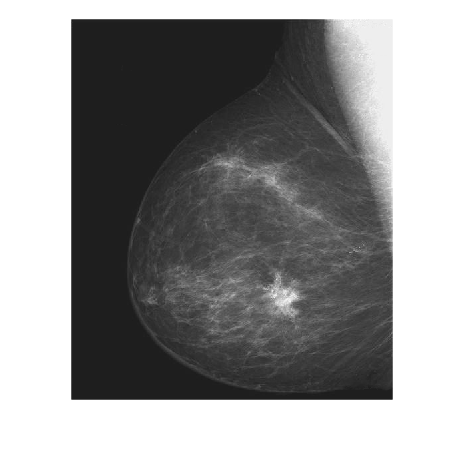

f = imread('inputs/breastXray.tif');
imshow(f);

Image info includes useful data such as file size, width, height, bit depth, colour type, byte order, compression etc.

Width = 482; Width/2 = 241

Height = 571; Height/2 = 285.5

f = imread('inputs/breastXray.tif');
f(3,10)             % print the intensity of pixel(3,10)

ans = uint8
28

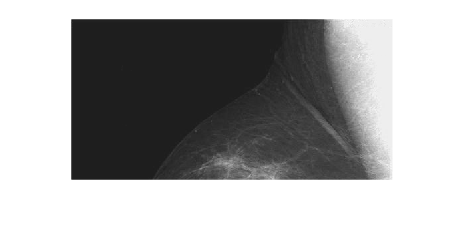

imshow(f(1:241,:))  % display only top half of the image

Indices of 2D matrix in Matlab is of the format: (row, column). You can use *':'* to *slice* the data. *(1:241 , : )* means only rows 1 to 241 and all columns are used. The default is the entire matrix.

% Finding maxium and minimum intensity values:
[fmin, fmax] = bounds(f(:))

fmin = uint8
21

fmax = uint8
255

fprintf("fmin: %fmin, fmax: %fmax\n", fmin, fmax);

fmin: 21.000000min, fmax: 255.000000max


The index ( : ) means every column. If not specified, MATLAB will return the max and min values for each column as 2 row vectors. - this could cause problems if the image is really big? e.g. high amount of printed output which is time consuming.

[fmin, fmax] = bounds(f)

fmin = 1×482 uint8 row vector
   23   21   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28


fmax = 1×482 uint8 row vector
   38   42   43   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33   33


Since the data type for *f* is *uint8*, the full intensity range is [0 255]. Is the intensity of *f* close to the full range?

Outcome: fmin = 21; fmax = 255

The lowest value is 21, and the highest value is 255. This means there is no true black (0) value in the image, only very dark grey values. 

### **Displaying only the right half of the image**

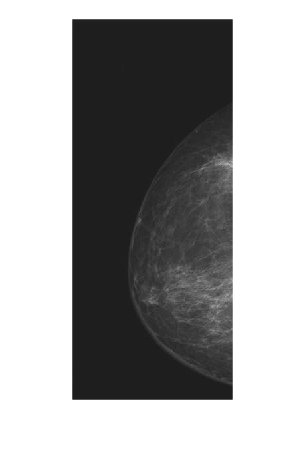

imshow(f(1:571,1:482/2)) 

imshow(f(:,1:241)) 

% this can be achieved in multiple ways but the second option is cleaner

### Negative Image

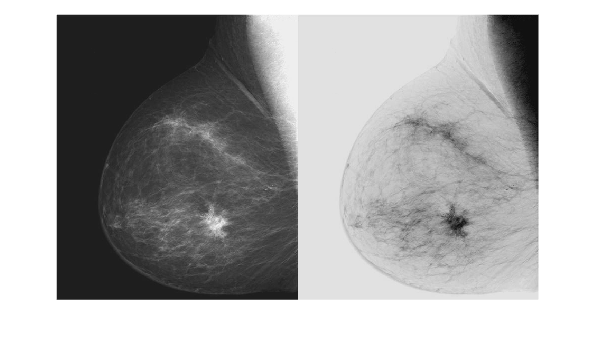

f = imread('inputs/breastXray.tif');
g1 = imadjust(f, [0 1], [1 0]);
montage({f, g1});

The second parameter of imadjust is in the form `[low_in, high_in]` 

The 3rd parameter is also in the form `[low_out, high_out]`

It spcifies how the input range is mapped to the output range. [1 0] means the lowest pixel intensity of the input is now mapped to the highest pixel intensity of the output and vice versa. This is why all the intensities are inverted and a negative image is produced.

The same thing can be achieved using function imcomplement.

### Trying out different adjustments:

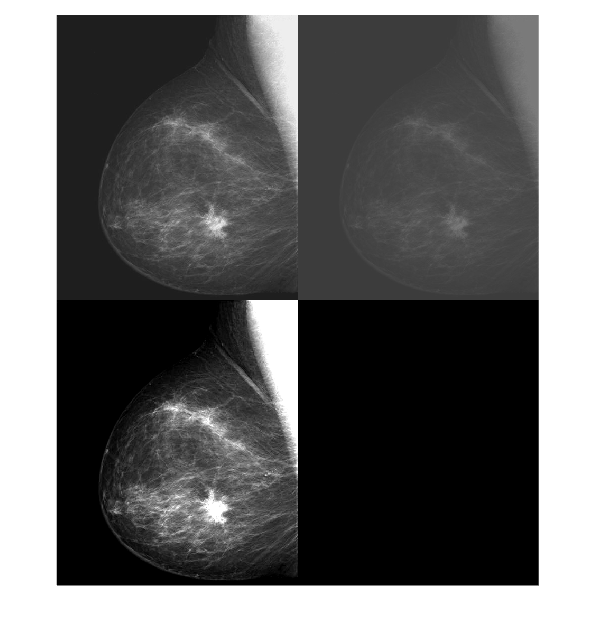

f = imread('inputs/breastXray.tif');

% this flattens the image
g2 = imadjust(f, [0 1], [0.2 0.5]);

% if both values were mapped to the same value the image would be completly flat:
% g2 = imadjust(f, [0 1], [0.5 0.5]); %middle value
% g2 = imadjust(f, [0 1], [0.2 0.2]); %darker value

%this allows you to darken the black values and brighten the white values:
g3 = imadjust(f, [0.15 0.65], [0 1]); 
% g3 = imadjust(f, [0.45 0.46], [0 1]); %similar to a threshold operation -
% image becomes nearly binary 

montage({f, g2, g3});

### Gamma Correction:

f = imread('inputs/breastXray.tif');
g2 = imadjust(f, [0.5 0.75], [0 1]); %values below 0.5 are set to 0 and values above 0.75 are set to 1
% this is why some detail is lost ^

g3 = imadjust(f, [ ], [ ], 2); %gamma correction where gamma=2
% low values become a lot darker
% high values only become a little darker

figure
disp("Gamme Correction:")

Gamme Correction:


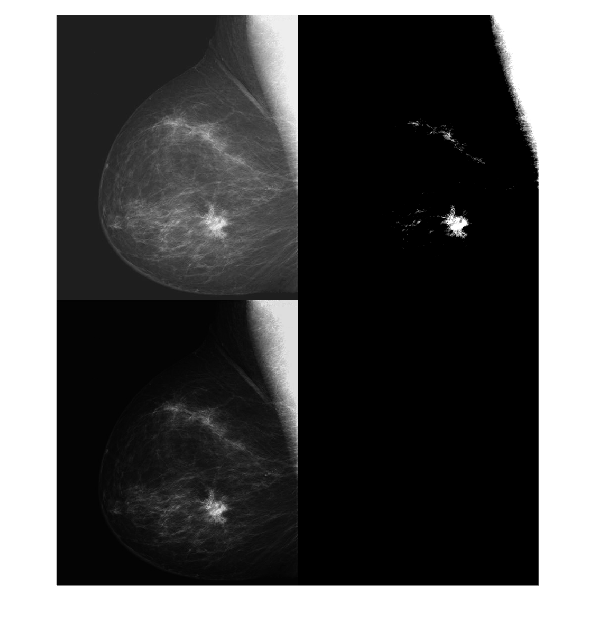

montage({f,g2,g3})

This produces a result similar to that of g2 by compressing the low end and expanding the high end of the gray scale. It however, unlike g2, retains more of the details because the intensity now covers the entire gray scale range.

*g3* uses gamma correct with gamma = 2.0 as shown in the diagram below. [ ] is the same as [0 1] by default.

## Task 2

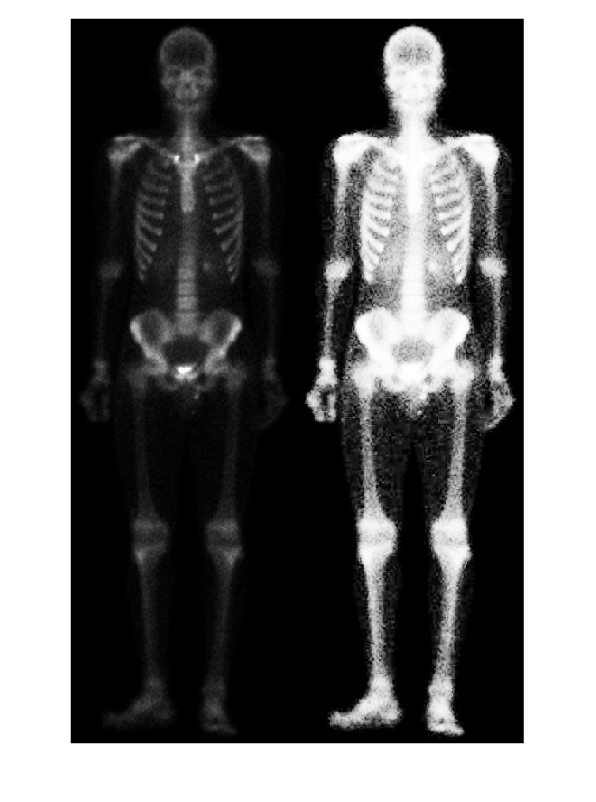

clear all; close all;
f = imread('inputs/bonescan-front.tif');

r = double(f);  % uint8 to double conversion
k = mean2(r);   % find mean intensity of image
E = 2;
s = 1 ./ (1.0 + (k ./ (r + eps)) .^ E);


g = uint8(255*s);
imshowpair(f, g, "montage")


$$s=T\left(r\right)=\frac{\left\lbrack 1\right\rbrack }{1+{\left(\frac{k}{r}\right)}^E }$$


Similar in shape to a sigmoid / logistic curve. Enhances contrast around k. 

`./` means element-wise division

`.^` means element-wise power

> Why do we perform the conversion to a double?

`uint8` can only store integers from 0-255 - division takes place `k/r` using a double enables division to function properly here.

> Why is EPS used?

E determines the steepness of the function. `eps` is a specal MATLAB constant which has the smallest value possible for double precision floating point numbers. This is necessary to avoid division by zero - maybe this could be useful in other applications too.

For values where r is close to 0, k/r becomes large - the denominator of s becomes large so s approaches 0

For values where r is close to 1 k/r becomes small  - the demminotor approaches 1 and s approaches 1 

The intensity values of s are normalized to the range of [0.0 1.0] and is in type *double*. Finally we scale this back to the range [0 255] and covert back to *uint8*.

**Discussion of results:**

The white parts of the image are much brighter - the contrast has been stretched enabling more of the skeleton features to be visible. 

## Task 3 - Contrast Enhancement using Histogram

Matlab has a built-in function *imhist* to compute the histogram of an image and plot it.

### Plotting the histogram of an image

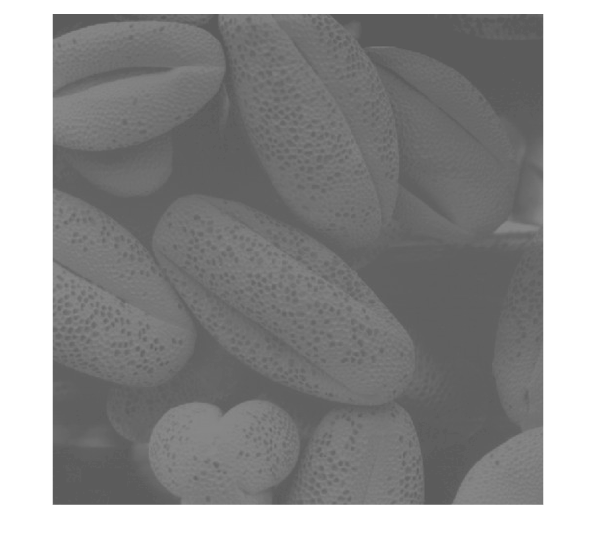

clear all       % clear all variables
close all       % close all figure windows
f=imread('inputs/pollen.tif');
montage({f}) 


disp("Histogram before processing:")

Histogram before processing:


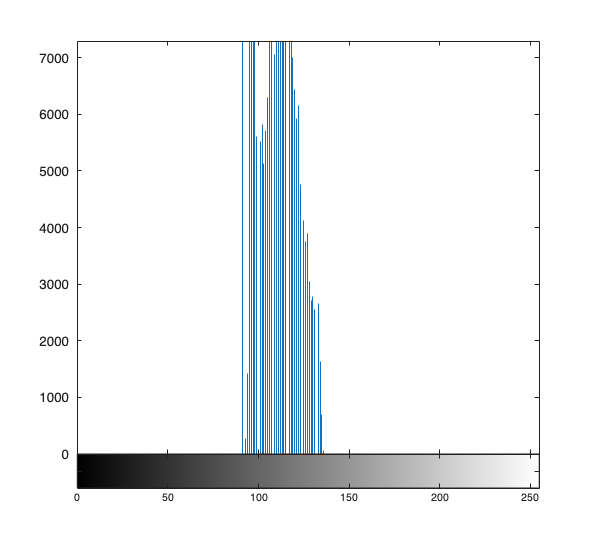

imhist(f);      % calculate and plot the histogram

The intensity level of this image is squashed between 70 to 140 in the range [0 255]. We may want to stretch this intensity to help improve the quality of the image. This can be done using the imadjust function. 

70/255 ~ 0.3

140/255 ~ 0.55

clear all       % clear all variables
close all       % close all figure windows
f=imread('inputs/pollen.tif');
g=imadjust(f,[0.3 0.55]); 

disp("Adjustment 1:")

Adjustment 1:


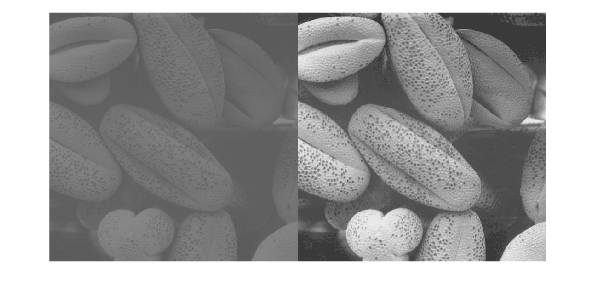

montage({f, g})     % display list of images side-by-side

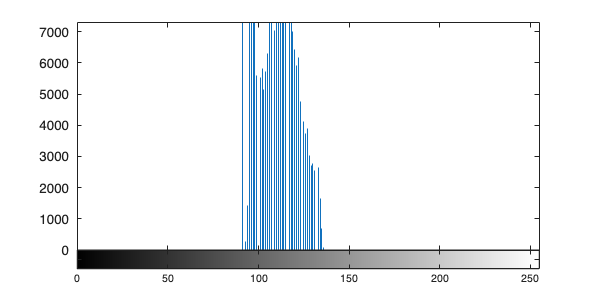


imhist(f);

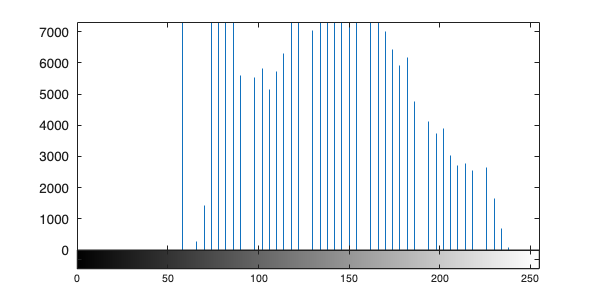

imhist(g);

disp("You can see this spreads out the histogram but not the full range.")

You can see this spreads out the histogram but not the full range.


### Histogram, PDF and CDF

PDF is the normalised histogram 

CDF is an integration of the cumulative sum of the PDF

numel returns the total number of elements in the matrix

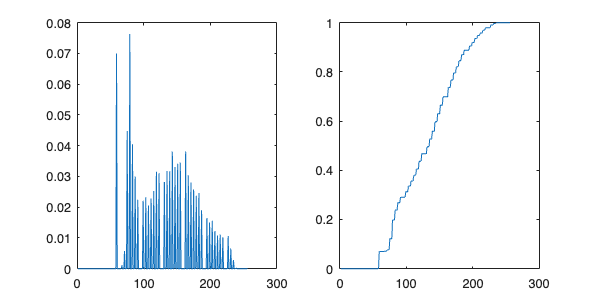

f=imread('inputs/pollen.tif');
g=imadjust(f,[0.3 0.55]); 
g_pdf = imhist(g) ./ numel(g);  % compute PDF reminder that ./ means element wise operation
g_cdf = cumsum(g_pdf);          % compute CDF

subplot(1,2,1)                  % plot 1 in a 1x2 subplot
plot(g_pdf)
subplot(1,2,2)                  % plot 2 in a 1x2 subplot
plot(g_cdf)

### Histogram Equalisation

To perform histogram equalisation the CDF is used as the intensity transformation function

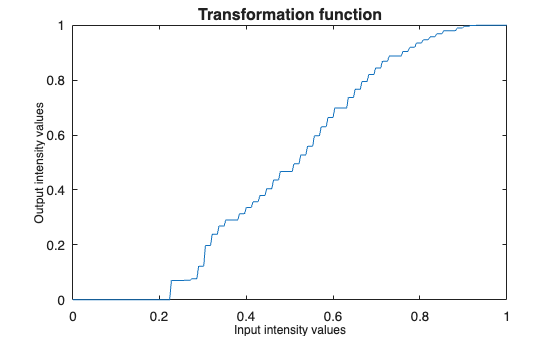

f=imread('inputs/pollen.tif');
g=imadjust(f,[0.3 0.55]); 
g_pdf = imhist(g) ./ numel(g);  % compute PDF reminder that ./ means element wise operation
g_cdf = cumsum(g_pdf);          % compute CDF

x = linspace(0, 1, 256);    % x has 256 values equally spaced
                            %  .... between 0 and 1
figure
plot(x, g_cdf)
axis([0 1 0 1])             % graph x and y range is 0 to 1
set(gca, 'xtick', 0:0.2:1)  % x tick marks are in steps of 0.2
set(gca, 'ytick', 0:0.2:1)
xlabel('Input intensity values', 'fontsize', 9)
ylabel('Output intensity values', 'fontsize', 9)
title('Transformation function', 'fontsize', 12)

histeq computes the CDF of an image and uses this as the intensity transformation function to flatten the histogram - this happens behind the scenes in MATLAB 

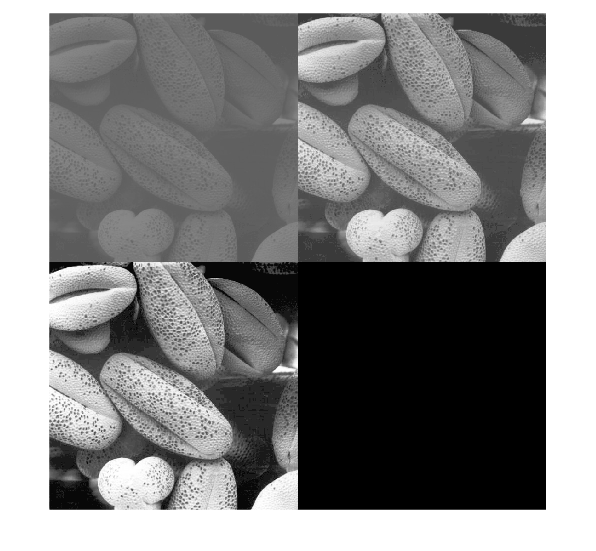

h = histeq(g,256);              % histogram equalize g
montage({f, g, h})

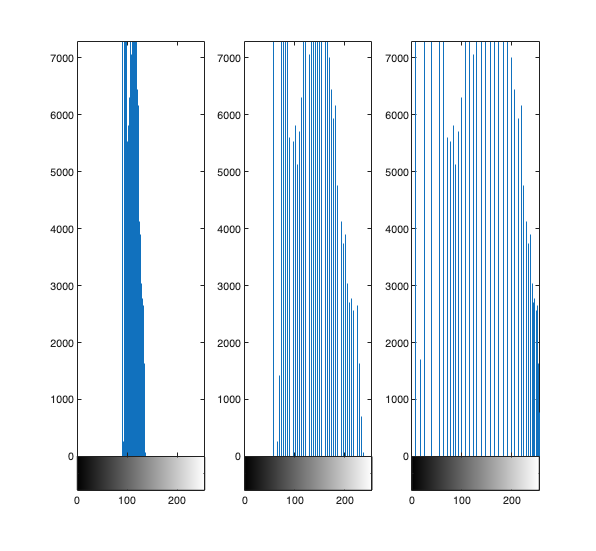

subplot(1,3,1); imhist(f);
subplot(1,3,2); imhist(g);
subplot(1,3,3); imhist(h);

## Task 4 - Noise Reduction with lowpass Filter

Different types of filter kernels: Averaging (box), Gaussian, Laplacian and Sobel. 

Types of kernels::

- 'average'

- 'disk'

- 'gaussian'

- 'laplacian'

- 'log'

- 'motion'

- 'prewitt'

- 'sobel'

- 'unsharp'

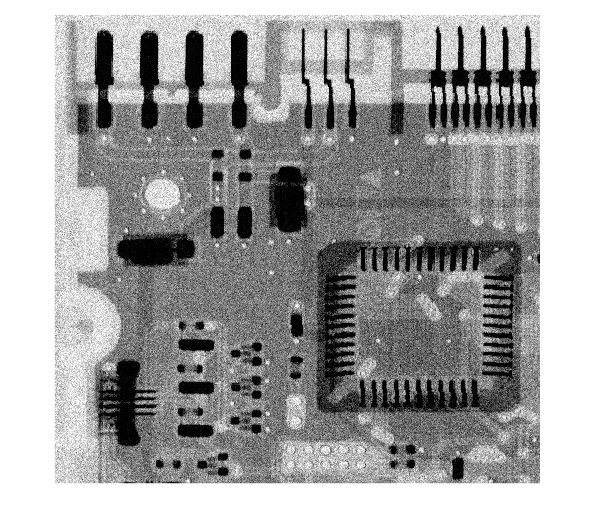

f = imread('inputs/noisyPCB.jpg');
% xray of printed circuit board
imshow(f)

w_box = fspecial('average', [9 9])

w_box =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


w_gauss = fspecial('Gaussian', [7 7], 1.0) %sigma=1, why? controls spread?

w_gauss =     0.0000    0.0002    0.0011    0.0018    0.0011    0.0002    0.0000
    0.0002    0.0029    0.0131    0.0216    0.0131    0.0029    0.0002
    0.0011    0.0131    0.0586    0.0966    0.0586    0.0131    0.0011
    0.0018    0.0216    0.0966    0.1592    0.0966    0.0216    0.0018
    0.0011    0.0131    0.0586    0.0966    0.0586    0.0131    0.0011
    0.0002    0.0029    0.0131    0.0216    0.0131    0.0029    0.0002
    0.0000    0.0002    0.0011    0.0018    0.0011    0.0002    0.0000


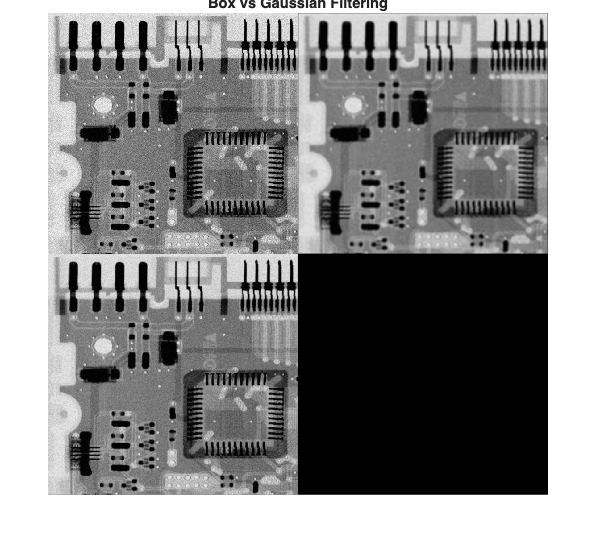


g_box = imfilter(f, w_box, 0);
g_gauss = imfilter(f, w_gauss, 0);

figure;
montage({f, g_box, g_gauss})
title("Box vs Gaussian Filtering")

Gaussian filtering produces less blurring because the kernel is weighted more highly at the centre as opposed to box filtering where each pixel in the kernel is weighted equally. Both remove some of the noise shown on the image.

Test yourself: Explore various kernel size and sigma value for these two filters. Comment on the trade-off between the choice of these parameters and the effect on the image.

clear all       % clear all variables
close all       % close all figure windows

f = imread('inputs/noisyPCB.jpg');

disp("Exploring different sigma values")

Exploring different sigma values


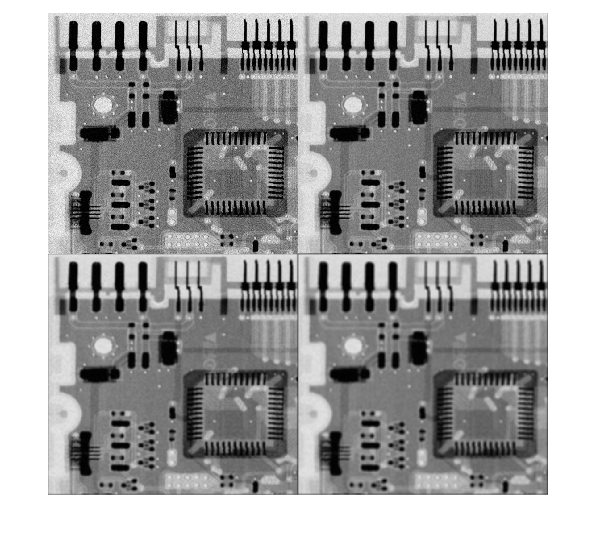


wg1 = fspecial('Gaussian', [12 12], 1.0);
wg2 = fspecial('Gaussian', [12 12], 3.0);
wg3 = fspecial('Gaussian', [12 12], 7.0);

g1 = imfilter(f, wg1, 0);
g2 = imfilter(f, wg2, 0);
g3 = imfilter(f, wg3, 0);

montage({f, g1, g2, g3});


% increasing the value of sigma increases the smoothing and reduces the
% sharpness of the image


clear all       % clear all variables
close all       % close all figure windows

w_box =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


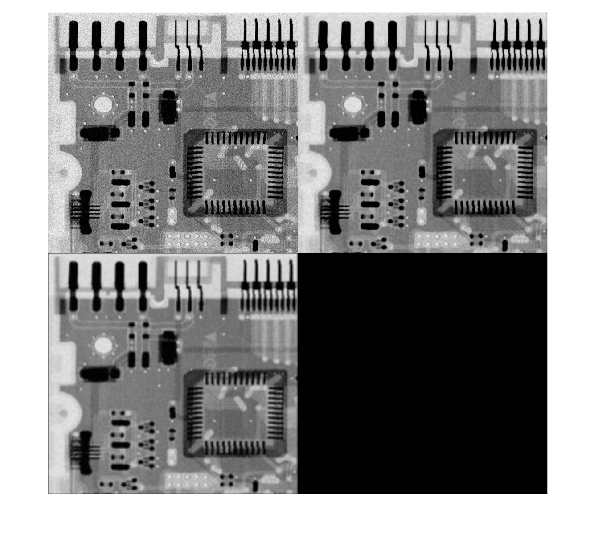


f = imread('assets/noisyPCB.jpg');

disp("Exploring different kernel sizes")


wg1 = fspecial('Gaussian', [7 7], 3.0);

Trying different sizes:


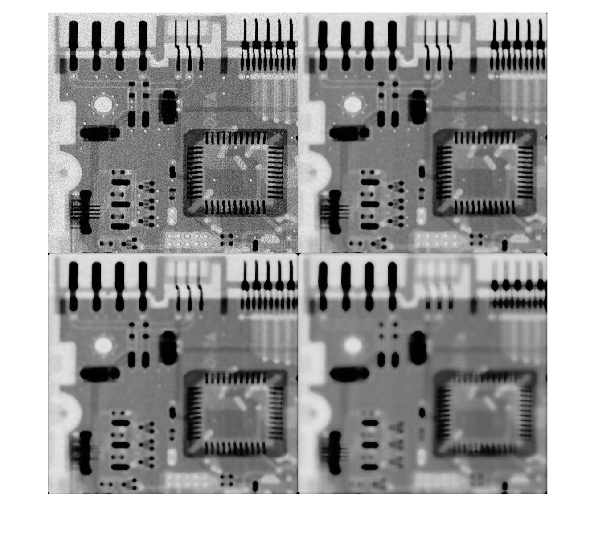

wg2 = fspecial('Gaussian', [15 15], 3.0);
wg3 = fspecial('Gaussian', [24 24], 3.0);

g1 = imfilter(f, wg1, 0);

g2 = imfilter(f, wg2, 0);
g3 = imfilter(f, wg3, 0);

montage({f, g1, g2, g3});

% increasing the kernel size increases the smoothing


A tradeoff has to be found between the smoothness and loss of detail

## Task 5 - Median Filtering

In both cases with Average and Gaussian filters, noise reduction is companied by reducing in the sharpness of the image. Median filter provides a better solution if sharpness is to be preserved. 

It's because it is useful for removing outliers.

f = imread('inputs/noisyPCB.jpg');
w_box = fspecial('average', [9 9])
g_box = imfilter(f, w_box, 0);

g_median = medfilt2(f, [7 7], 'zero');
montage({f, g_median, g_box})

You can visibly see the image is less blurry

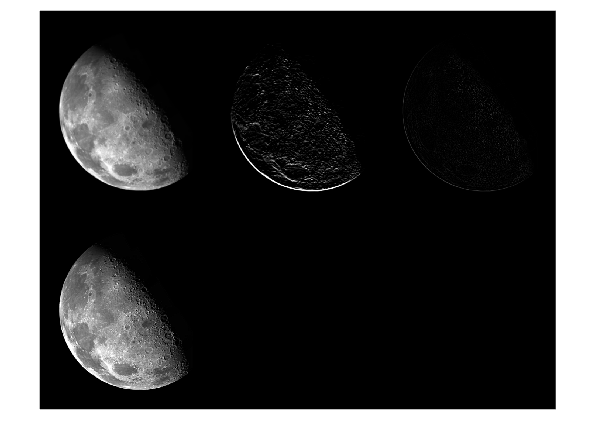

disp("Trying different sizes:")

med1 = medfilt2(f, [10 10], 'zero');
med2 = medfilt2(f, [15 15], 'zero');
med3 = medfilt2(f, [25 25], 'zero');
montage({f, med1, med2, med3})

Median filtering is good at removing things like salt and pepper noise because it takes the median value from a region rather than averaging - which reduces the blurring effect.

## Task 6 - Sharpening the image with Laplacian, Sobel and Unsharp filters

Now that you are familiar with the Matlab functions *fspecial* and *imfilter*, explore with various filter kernels to sharpen the moon image stored in the file *moon.tif*. The goal is to make the moon photo sharper so that the craters can be observed better.

f = imread('inputs/moon.tif');

sobel = fspecial('sobel');
l = fspecial('laplacian');
u = fspecial('unsharp');

g2 = imfilter(f, sobel);
g3 = imfilter(f, l);
g4 = imfilter(f, u);
montage({f, g2, g3, g4});

imwrite(g4, 'outputs/lab-3-moon-craters.png');


Sobel approximates first derivative 

Laplacian approximates the second deriative

Unsharp is probably best here for highlighting the craters. The others are not so good at highlighting the craters.

# Challenges 1-3 are in `challenges.mlx`